# Autômato Celular para Distribuição de Litofacies *versão 0.3*

#### Inicialização das células (randomicamente)

clear all

vetor=[0 1 2]

vetor =      0     1     2


celulas=vetor(randi(numel(2*vetor),50))

celulas =      2     2     0     2     1     1     1     2     2     2     1     2     2     1     0     1     1     1     2     0     2     1     2     2     2     0     1     2     2     2     1     1     2     1     0     0     1     2     2     2     2     1     0     1     0     2     1     0     2     1
     2     0     1     0     1     2     1     1     1     1     0     2     1     0     1     1     1     1     0     1     0     2     1     0     2     1     2     0     2     2     2     1     2     2     1     1     0     1     2     2     2     2     0     1     2     2     1     2     2     2
     1     2     2     1     0     2     2     1     2     0     2     1     0     2     1     0     0     0     1     2     0     1     2     2     2     2     1     1     0     1     2     1     0     2     2     2     0     1     0     0     2     0     0     2     1     0     0     0     2     2
     0     2     0     1     1     2     1     0     0     0     2     0     1     2   

n0=0;
n1=0;
n2=0;

#### Loop principal que determina o número de iterações do algoritmo

-Os blocos são de 5x5 percorridos de cima para baixo, da esquerda para a direita.

itmax=15

itmax = 15



for a=1:itmax
    
    %centro do grid
    for i=3:48
        for j=3:48
            if celulas(i,j)==0
                for l=i-2:i+2
                    for k=j-2:j+2
                        if celulas(l,k)==0
                            n0=n0+1;
                        else if celulas(l,k)==1
                                n1=n1+1;
                            else
                                n2=n2+1;
                            end
                        end
                    end
                end
                if n0~=0
                    n0=n0-1;
                end
            end
            if celulas(i,j)==1
                for l=i-2:i+2
                    for k=j-2:j+2
                        if celulas(l,k)==0
                            n0=n0+1;
                        else if celulas(l,k)==1
                                n1=n1+1;
                            else
                                n2=n2+1;
                            end
                        end
                    end
                end
                if n0~=0
                    n1=n1-1;
                end
            end
            if celulas(i,j)==2
                for l=i-2:i+2
                    for k=j-2:j+2
                        if celulas(l,k)==0
                            n0=n0+1;
                        else if celulas(l,k)==1
                                n1=n1+1;
                            else
                                n2=n2+1;
                            end
                        end
                    end
                end
                if n2~=0
                    n2=n2-1;
                end
            end

#### Neste bloco estão as regras (que podem ser alteradas pelo usuário)

Se a célula central não é vazia:

Regra 1: Permanece no mesmo estado se $4 \leq n \leq 10$.

Regra 1.1: Fica vazia se $n\leq 3$ ou $n \geq 11$.

Se a célula central é vazia:

Regra 2.1: A célula é colonizada se $6 \leq n \leq 10$.

Regra 2.2: Permanece no mesmo estado caso contrário.

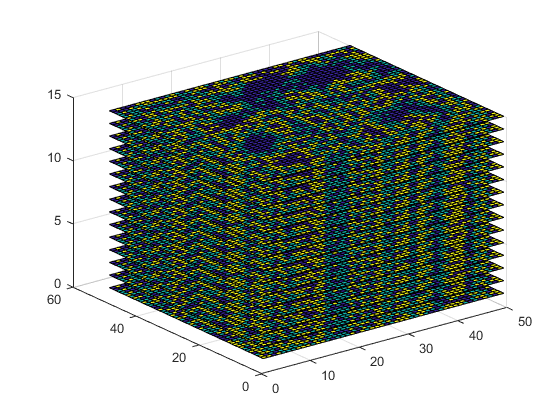

            %Regras
            [celulas,n0,n1,n2]=regras(celulas,n0,n1,n2,i,j);
        end
    end
    

view(3)
colormap("parula")

x = (1:1:50);
y = (1:1:50);
z=x.^2+y.^2;
[X,Y,Z] = meshgrid(x,y,z);
d=a*ones(50,50)+zeros(50,50);
plot(a)=surf(X(:,:,1),Y(:,:,1),d,celulas);
hold on
end